# Temperature and Heat Flux over X-43 Geometry

%% Constants and Variable Initialization
% Air foil and Wedge Geometry
x = [1 1 1 1]; % [m]
alpha = [5 5 5 5]; % [deg]
R_le = 0.003; % [m]
n_points = 40;


% atmospheric flow conditions
M = [5 7 10];
H = [24.5 29.0 3.8]; % [km]
Vinf = [1490 2107 3061]; % [m/s]
Tinf = [221.08 225.48 233.11]; % [K]
Pinf = [2743.6 1399.6 685.7]; % [Pa]
T0 = [1326.46 2435.13 4895.31]; % [K]
AoA = [4 6 8 10]; % [deg]
gamma = 1.362; % [-]
R = 287; % [J/(kg-K)]
Pr = 0.715; % Prandtl number
rec_fac = sqrt(Pr); % recovery factor
sigma = 5.67e-8; % stefan-botlzmann constant
epsilon = 0.95; % emissivity for carbon-carbon
CPw = 1700; % [J/(kg-K)], value for carbon-carbon
CPinf = 1006; % [J/(kg-K)], value for air
mu_ref = 1.827e-5; % [kg/(m-s)]
Tref = 291.15; % [K]
C = 120; % [K]

gp1 = gamma + 1;
gm1 = gamma - 1;
ggm1 = gamma / (gamma - 1);
s = zeros(length(M),1);


%% Heat Flux
for aoa = 1:length(AoA)
for mach = 1:length(M)

% Leading Edge Stagnation Point
    % Freestream conditions
    Tst(mach) = T0(mach) * (1 + gm1 / 2 * M(mach)^2)^(-1); % static temp
    P0(mach) = Pinf(mach) * (1 + gm1 / 2 * M(mach)^2)^(ggm1);
    rho_inf(mach) = Pinf(mach) / (R * Tinf(mach)); % air density at stagnation
    
    % normal shock relations
    Pst(mach) = P0(mach) * ((gp1 * M(mach)^2) / (2 + gm1 * M(mach)^2))^(ggm1)*...
        (gp1 / (2 * gamma * M(mach)^2 - gm1))^(1 / gm1);
    rho_st(mach) = rho_inf(mach) * (gp1 * M(mach)^2) / (gm1 * M(mach)^2 + 2);
    mu_st(mach) = mu_ref * ((Tref + C) / (T0(mach) + C)) * (T0(mach) / Tref)^(3/2);
    
    % adiabatic enthalpy at wall
    h_aw(mach) = CPinf * T0(mach) + 0.5 * Vinf(mach)^2;
    
    % delta V at boundary layer edge?
    Du_stDs(mach) = (1 / R_le) * sqrt(2 * (P0(mach) - Pinf(mach)) / rho_st(mach));
    
    % Tiso solution
    syms T_ISO 
    q_r_pt = sigma * epsilon * (T_ISO^4);
    h_staw_pt = CPinf * T0(mach) + 0.5 * Vinf(mach)^2;
    h_w_pt = CPw * T_ISO;
    q_st_gw_pt = 0.57 * Pr^(-0.6) * sqrt(rho_st(mach) * mu_st(mach)) * ...
        (h_staw_pt - h_w_pt) * sqrt(Du_stDs(mach));
    FUNC_pt = q_st_gw_pt - q_r_pt;
    func_pt = matlabFunction(FUNC_pt);
    Tiso_pt = fzero(func_pt,1000,optimset('Display','off'));
    
    % enthalpies and heat flux
    h_w_pt_func = matlabFunction(h_w_pt);
    h_w_pt = h_w_pt_func(Tiso_pt);
    q_st_gw_pt_func = matlabFunction(q_st_gw_pt);
    q_st_gw_pt_val = q_st_gw_pt_func(Tiso_pt);
    
    Tiso(mach,1) = Tiso_pt;
    Qiso(mach,1) = q_st_gw_pt_val;
    % Tw(1) = Tiso(mach);
    % q_w(1) = q_stgw(mach,1);

% Leading Edge Tip Curvature
    % tip radius parameters
    tip_min = 0;
    tip_max = (pi / 2) - deg2rad(alpha(3));
    dTip = (tip_max - tip_min) / 20;
    q_tip_gw(mach,1) = q_st_gw_pt_val;
    
    ilast = 20;
    for i = 2:ilast
        tip = tip_min + dTip * (i - 1);
        s(mach,i) = tip * R_le;
    
        G = (1 - 1 / (gamma * M(mach)^2)) * (tip^2 - 0.5 * tip * sin(4 * tip) + ((1 - cos(4 * tip)) / 8)) + (4 / (gamma * M(mach)^2)) * (tip^2 - tip * sin(2 * tip) + 0.5 * (1 - cos(2 * tip)));

        q_tip_gw(mach,i) = q_st_gw_pt_val * 2 * tip * sin(tip) * ((1 - 1 / (gamma * M(mach)^2)) * cos(tip)^2 + 1 / (gamma * M(mach)^2)) * G^(-1/2);

        Qiso(mach,i) = q_tip_gw(mach,i);
        Tiso(mach,i) = Tiso_pt;
    
    end

% Leading-edge Flat Surface Heat Flux
    % lower surface
    if AoA(aoa) < 0 && abs(AoA(aoa)) > alpha(3) % prandtl-meyer fan
        theta = abs(AoA(aoa) + alpha(3));
        [M3(mach), P3(mach), T3(mach)] = PM_sol2(theta,M(mach),Pinf(mach),Tinf(mach),gamma);
    elseif AoA(aoa) >= 0 % shock
        theta = AoA(aoa) + alpha(3);
        [M3(mach),P3(mach),T3(mach)] = oblique2(theta,M(mach),Pinf(mach),Tinf(mach),gamma);
    end
    
    V3(mach) = M3(mach) * sqrt(R * gamma * T3(mach));
    rho3(mach) = P3(mach) / (R * T3(mach));
    h_eaw3(mach) = CPinf * T3(mach) + rec_fac * 0.5 * V3(mach)^2;
    
    % Stanton Number
    y = cosd(alpha(3)) * R_le * sind(alpha(3));
    s_max = x(3) / cosd(alpha(3));
    ds = (s_max - s(mach,ilast)) / (n_points - 1);

    % Match location and thermal calculations for plots
    syms T_ISO
    for i = 1:40
        ii = ilast + i;
        s(mach,ii) = s(mach,ilast) + i * ds;
        mu3 = mu_ref * ((Tref + C) / (T3(mach) + C)) * (T3(mach) / ...
            Tref)^(3/2);
        Re_y = rho3(mach) * V3(mach) * (s(mach,ii) + y - s(mach,ilast)) / mu3;
    
        Tstar_T3 = 0.5 + 0.039 * M3(mach)^2 + 0.5 * (T_ISO / T3(mach));
        Cf_star = 0.664 * (Tstar_T3^(-1/6)) * (Re_y^(-1/2));
        Pr_star = (((T_ISO / T3(mach)) - 1) * (2 / (gm1 * M3(mach)^2)))^2;
        C_H = Cf_star / (2 * (Pr_star^(2/3)));
        
        h_w_flat = CPw * T_ISO;
        q_f_gw = C_H * rho3(mach) * V3(mach) * (h_eaw3(mach) - h_w_flat);
        q_r_flat = sigma * epsilon * T_ISO^4;
    
        func = q_f_gw - q_r_flat;
        FUNC = matlabFunction(func);
        Tiso(mach,ii) = fzero(FUNC,Tiso(mach),optimset('Display', 'off'));
        s_T(mach,i) = s(mach,ii);
        q_f_gw_func = matlabFunction(q_f_gw);
        Qiso(mach,ii) = q_f_gw_func(Tiso(mach,ii));
    
    end
end
end


## Plotting

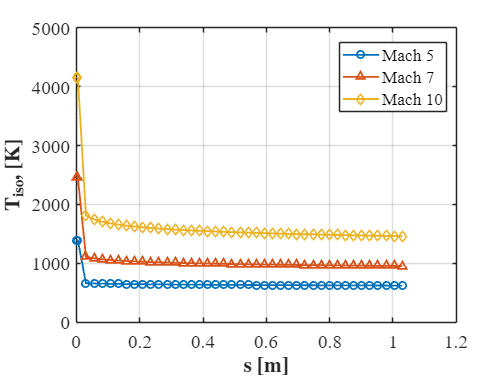

% Set Plotting parameters
set(0, 'DefaultAxesFontName', 'Times New Roman');  % font stlye
set(0, 'DefaultAxesFontSize', 16);       % font size
set(0, 'DefaultTextFontName', 'Times New Roman');  % font style
set(0, 'DefaultTextFontSize', 16);       % font size
set(0, 'DefaultLineLineWidth', 1.5);       % line width
set(0, 'DefaultLineMarkerSize', 6);      % marker size
set(0, 'DefaultTextInterpreter', 'latex');

fign = 1;
figure(fign)
plot(s(1,:),Tiso(1,:),'-o',s(2,:),Tiso(2,:),'-^',s(3,:),Tiso(3,:),'-diamond');
xlabel('\textbf{s [m]}');
ylabel('\textbf{$\mathbf{T_{iso}}$, [K]}');
legend('Mach 5','Mach 7','Mach 10','Location','best');
grid on;

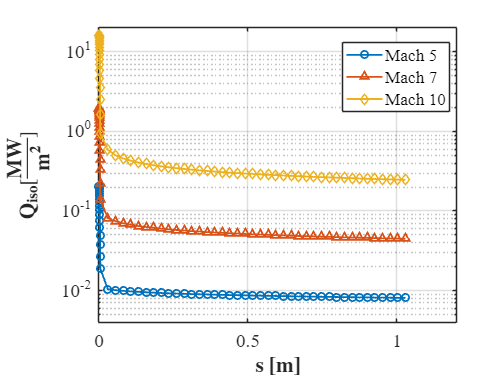

fign = fign + 1;

figure(fign)
semilogy(s(1,:),Qiso(1,:)*10^-6,'-o',s(2,:),Qiso(2,:)*10^-6,'-^',s(3,:),Qiso(3,:)*10^-6,'-diamond');
ylim([4*10^-3,2*10^1])
xlabel('\textbf{s [m]}');
ylabel('$\mathbf{Q_{iso}}$[$\mathbf{\frac{MW}{m^2}}$]');
legend('Mach 5','Mach 7','Mach 10','Location','best');
grid on;

fign = fign + 1;














